Load swingDAQ data

% Load Data
load swingdata.mat

% If you want to write to excel, uncomment
% writetable(acquiredData, "swingdata.xlsx");

% Remove possible spikes from LC1 to LC6
LC1 = removespikes(acquiredData.LC1);
LC2 = removespikes(acquiredData.LC2);
LC3 = removespikes(acquiredData.LC3);
LC4 = removespikes(acquiredData.LC4);
LC5 = removespikes(acquiredData.LC5);
LC6 = removespikes(acquiredData.LC6);

Load Phone Data

% Load Data
load phonedata.mat

Acceleration = renamevars(Acceleration, ["X","Y","Z"],...
["AccelX","AccelY","AccelZ"]);
AngularVelocity = renamevars(AngularVelocity, ["X","Y","Z"],...
["OmegaY","OmegaX","OmegaZ"]);
Orientation = renamevars(Orientation, ["X","Y","Z"],...
["OrientX","OrientY","OrientZ"]); % Note the switch in order
% because of naming convention in
% MATLAB Mobile/iphone

phoneData = synchronize(Acceleration, AngularVelocity, Orientation, ...
'union', 'linear'); % Merge the three timetables into one
% If want to write to Excel, uncomment
% writetimetable(phoneData,"phoneData.xlsx");

toffset = -17.677; % offset between swing and phone data obtained
% by comparing peaks in OrientY
t_phone = second(phoneData.Timestamp,"secondofday");
t_phone = t_phone - t_phone(1)-toffset;
clear Acceleration AngularVelocity Orientation

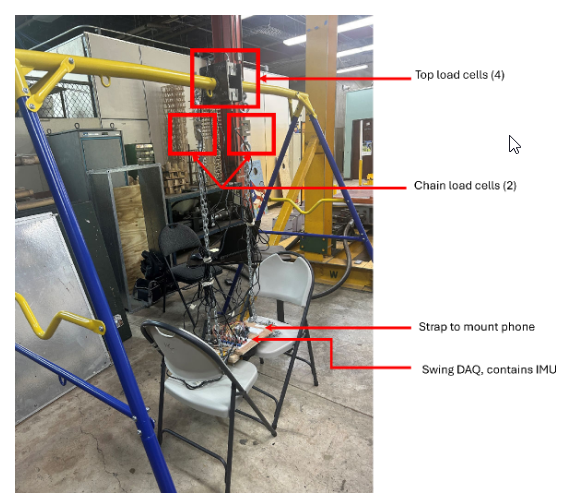

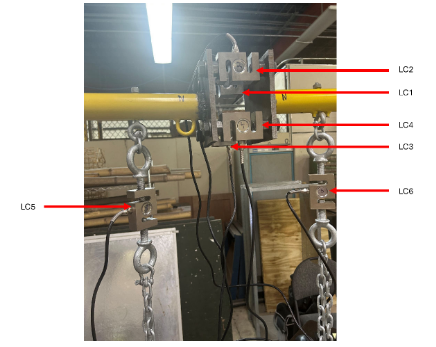

Purposes:

- IMU - Measure acceleration and angular velocity. Estimate orientation.

- LC5 & LC6 - Measure Chain Tension.

- LC1 through LC4 - Measure Beam Bending Moment.

What we need to measure from our datasets: